### Leakage probabilities of each energy state

clear all; 

%%% evaluation of leakages prob %%%
tic
R=1; %radius of the shield 
sigma=0.5;
% pa=0.2;
% ps=1-pa;

% define vector of the possible energy states (last element 0 means the RW has ended)
nstates=4;
arrival_states=[1:nstates 0];

% Probability matrix (i rows, j columns) for the transitions from one state to another due to scattering
% NOTE: last element of each column is the probability that RW end in j-th state
p_s(:,1)=[0.25 0.23 0.2 0.12 0.2]'; %1st column: transitions from state 1
p_s(:,2)=[0.1 0.26 0.24 0.3 0.1]'; %2nd column: transitions from state 2
p_s(:,3)=[0.05 0.2 0.3 0.3 0.15]'; %3rd column: transitions from state 3
p_s(:,4)=[0.25 0.35 0.15 0.2 0.05]'; %4th column: transitions from state 4

% cumulative
cum_p_s=zeros(length(p_s(:,1))+1,nstates);
for ii=1:length(p_s(:,1))    
    cum_p_s(ii+1,:)=cum_p_s(ii,:)+p_s(ii,:);
end

err=1;
toll=0.03;
i=1;

samp_av_r(1,1:nstates)=0;
var_r(1,1:nstates)=0;
RSD_r(1,1:nstates)=0;
csi(1,1:nstates)=0;
mom_2_r(1,1:nstates)=0;


while err>toll || i<100
    x0=0;y0=0;z0=0;
    vita=1;
    % start RW at the energy state 1
    en_state_old=1;
    leakage=zeros(1, nstates); % random variable for each state for the i-th RW
    while vita==1
        mu=-1+2*rand;
        phi=2*pi*rand;
        l=-1/sigma*log(rand);
        
        x=x0+l*cos(phi)*sqrt(1-mu^2);
        y=y0+l*sin(phi)*sqrt(1-mu^2);
        z=z0+l*mu;
        
        volo=sqrt(x^2+y^2+z^2);
        
        if volo>R 
            %leaked out
            leakage(en_state_old)=1;
            vita=0;
        elseif volo<=R 
                %still in the medium 
                state_index=find(cum_p_s(:,en_state_old)<rand, 1, 'last' );
                en_state_old=arrival_states(state_index);
                if en_state_old==0
                    %particle absorbed 
                    vita=0;
                else  
                    x0=x;y0=y;z0=z;
                end
        end
        
        
    end

    csi(i,1:nstates)=leakage;
    samp_av_r(i,:)=sum(csi,1)/i;
    mom_2_r(i,:)=sum(csi.^2,1)/i;
    var_r(i,:)=mom_2_r(i,:)-samp_av_r(i,:).^2;
    RSD_r(i,:)=sqrt(var_r(i,:)/i)./samp_av_r(i,:);
    
    err=max(RSD_r(i,:));
    
    
    i=i+1;

    
end

time = toc

time = 1.4842

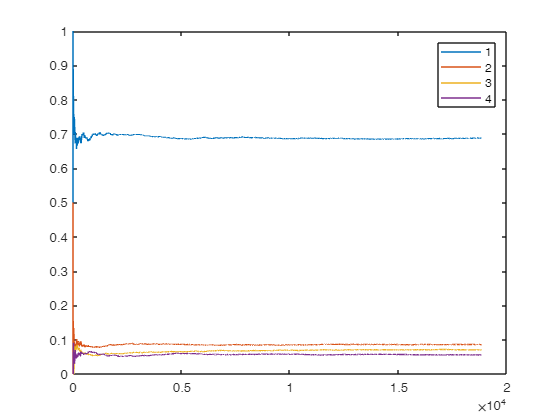

%histogram(check_CLT_samp_av)
plot(samp_av_r)
legend('1','2','3','4')

%plot(RSD_r)

### Absorption probability in tumor cell for radiation in group 3

clear all; 

%%% evaluation of leakages prob %%%
tic
R=1; %radius of the shield 
sigma=1.1;
% pa=0.2;
% ps=1-pa;

% tumor geometry
r_tumor=0.3; %radius
xc_tumor=0.2;yc_tumor=0.2;zc_tumor=0.2; %center coordinates

% define vector of the possible energy states (last element 0 means the RW has ended)
nstates=4;
arrival_states=[1:nstates 0];

% Probability matrix (i rows, j columns) for the transitions from one state to another due to scattering
% NOTE: last element of each column is the probability that RW end in j-th state
p_s(:,1)=[0.15 0.13 0.4 0.12 0.2]'; %1st column: transitions from state 1
p_s(:,2)=[0.1 0.26 0.39 0.15 0.1]'; %2nd column: transitions from state 2
p_s(:,3)=[0.05 0.1 0.15 0.1 0.6]'; %3rd column: transitions from state 3
p_s(:,4)=[0.20 0.15 0.40 0.2 0.05]'; %4th column: transitions from state 4

% cumulative
cum_p_s=zeros(length(p_s(:,1))+1,nstates);
for ii=1:length(p_s(:,1))    
    cum_p_s(ii+1,:)=cum_p_s(ii,:)+p_s(ii,:);
end

err=1;
toll=0.03;
i=1;

samp_av_r=0;
var_r=0;
RSD_r=0;
csi=0;
mom_2_r=0;


while err>toll || i<100
    x0=0;y0=0;z0=0;
    vita=1;
    % start RW at the energy state 1
    en_state_old=1;
    csi(i)=0;
    while vita==1
        mu=-1+2*rand;
        phi=2*pi*rand;
        l=-1/sigma*log(rand);
        
        x=x0+l*cos(phi)*sqrt(1-mu^2);
        y=y0+l*sin(phi)*sqrt(1-mu^2);
        z=z0+l*mu;
        
        volo=sqrt(x^2+y^2+z^2);
        
        if volo>R 
            %leaked out
            vita=0;
        elseif volo<=R 
                %still in the medium 
                state_index=find(cum_p_s(:,en_state_old)<rand, 1, 'last' );
                en_state_new=arrival_states(state_index);

                if en_state_new(cum_p_s(:,1)<rand)==0
                    %particle absorbed 
                    vita=0;
                    if en_state_old==3 && sqrt((x-xc_tumor)^2+(y-yc_tumor)^2+(z-zc_tumor)^2)<=r_tumor
                        csi(i)=1;
                    end
                    % possible improvement:
                    % csi(i)=1*(en_state_old==3 && sqrt((x-xc_tumor)^2+(y-yc_tumor)^2+(z-zc_tumor)^2)<=r_tumor)+0;
                else
                    %scattering
                    x0=x;y0=y;z0=z;
                end
%                 en_state_old=en_state_new;
                en_state_old=arrival_state(length(cum_p_s(cum_p_s(:,en_state_old)<rand,1)))==0;
        end
        
        
    end

    samp_av_r(i)=sum(csi)/i;
    mom_2_r(i)=sum(csi.^2)/i;
    var_r(i)=mom_2_r(i)-samp_av_r(i).^2;
    RSD_r(i)=sqrt(var_r(i)/i)./samp_av_r(i);
    
    err=RSD_r(i);
    
    
    i=i+1;
%     i

    
end


time = toc

time = 6.0748

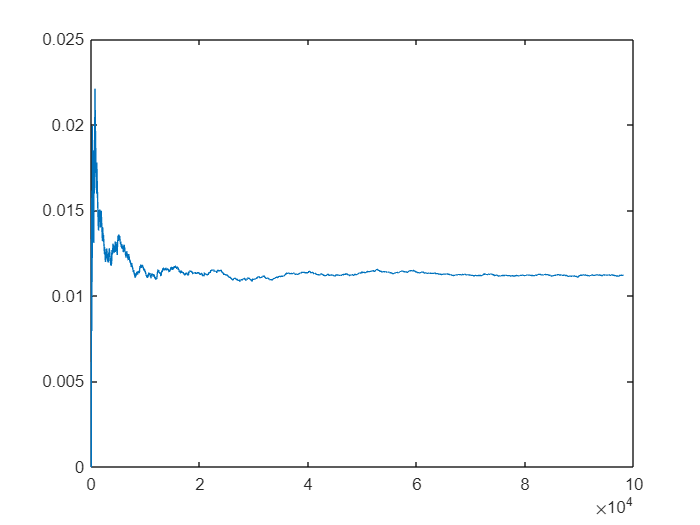

figure
plot(samp_av_r)